## H的初始值计算

将缆索视为抛物线来计算H的初始值。

如图所示，将悬链线视为等代简支梁，跨中弯矩$M_m =\frac{\mathrm{qD}\left(L-D\right)}{4}+\frac{{\mathrm{qD}}^2 }{8}$，那么跨中处的水平力$H$与跨中处的垂度$f$的乘积就等于$M_m$，即：


$$M_m =\frac{q\;D\;\left(L-D\right)}{4}+\frac{{q\;D}^2 }{8}=H\;f$$


计算得：


$$H=\frac{1}{f}\left(\frac{q\;D\;\left(L-D\right)}{4}+\frac{{q\;D}^2 }{8}\right)$$


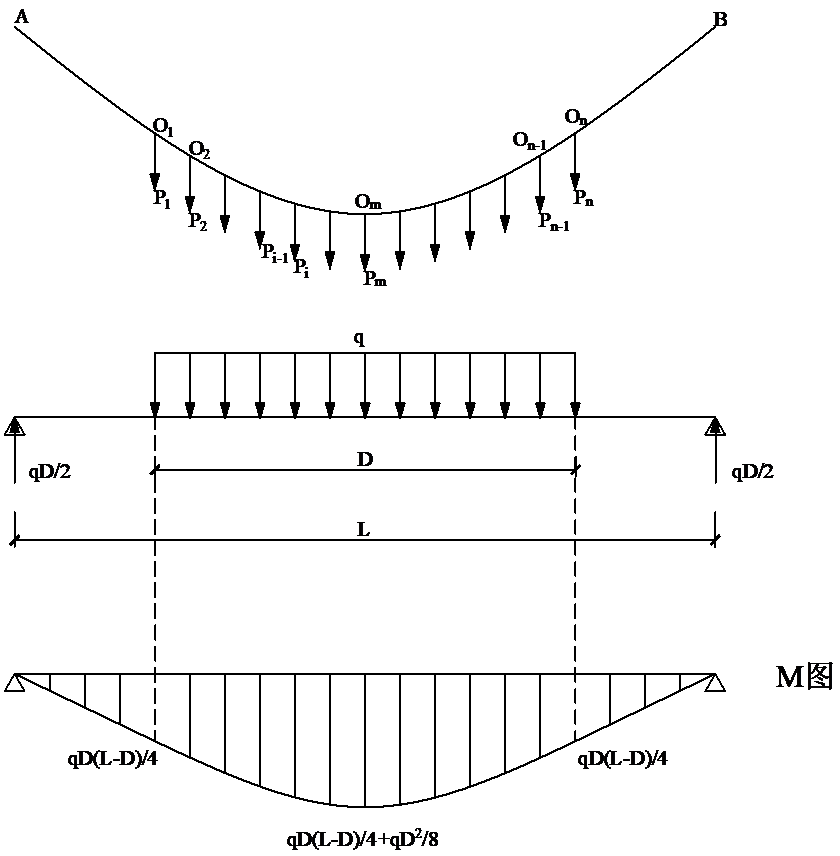

function H = Init_H()
    load InitData
    
    q = q_cable + q_beam; % 等代荷载集度q，包括主缆的集度和加劲梁的集度
    D = l_beam_seg * (n+1); % 吊杆区长度D
    L = sum(Li); % 跨径L
    f = hA-hOm; % 垂度f
    
    H = 1/f * ((q*D*(L-D)/4)+(q*D^2)/8);
end